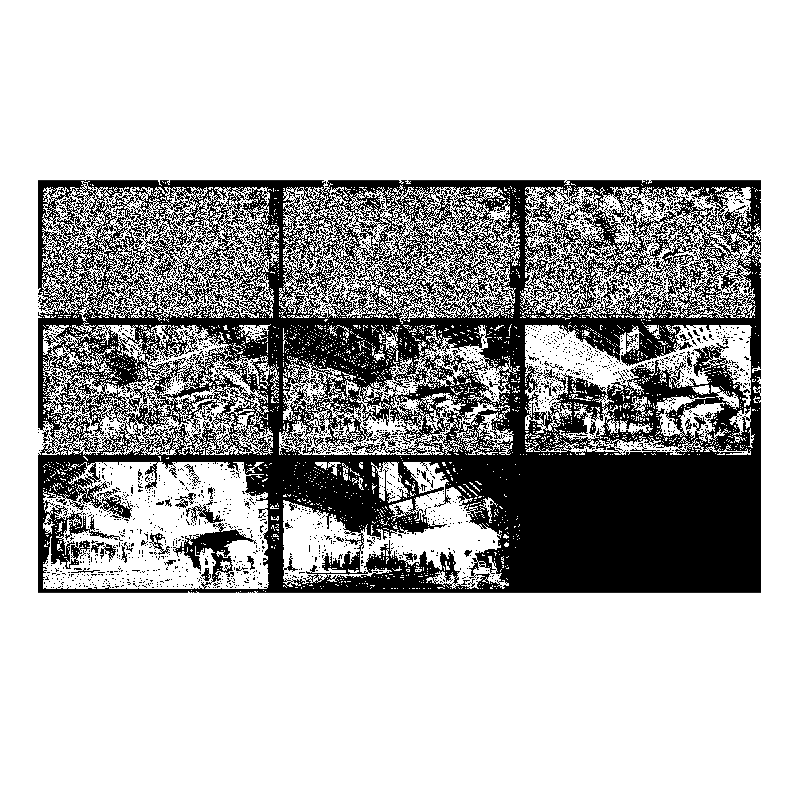

x = imread("../images/greyscale1.jpg");
image_shape = size(x);
channels = 1;
num_bits = 8;
num_images = channels * num_bits;
images = zeros(image_shape(1), image_shape(2), num_images, 'logical');
for img = 1:num_images
    channel_idx = idivide(uint8(img) - 1, num_bits) + 1;
    image_channel = x(:,:, channel_idx);
    images(:, :, img) = mod(floor(image_channel/2 ^ (mod(img-1, num_bits))), 2);
end

montage(images)

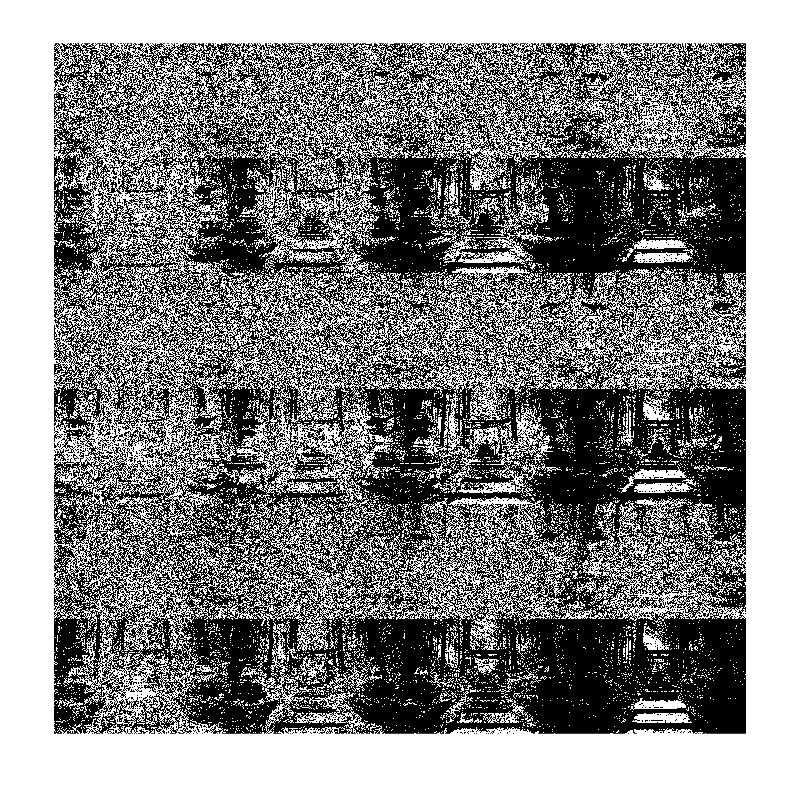

x = imread("../images/rgb1.jpg");
image_shape = size(x);
channels = 3;
num_bits = 8;
num_images = channels * num_bits;
images = zeros(image_shape(1), image_shape(2), num_images, 'logical');
for img = 1:num_images
    channel_idx = idivide(uint8(img) - 1, num_bits) + 1;
    image_channel = x(:,:, channel_idx);
    images(:, :, img) = mod(floor(image_channel/2 ^ (mod(img-1, num_bits))), 2);
end

montage(images)